# Supplemental information from command histories,

# requiring editing before formally implementing in project classes 

## Create IDIF & Twilite AIF "*-embed.nii.gz" needed by PycharmProjects/dynesty/idif2024 for class Huang1980Model & Ichise2002Model

cd('/Volumes/PrecunealSSD/Singularity/CCIR_01211/derivatives/sub-108306/ses-20230227103048/pet')
idif = mlfourd.ImagingFormatContext2("sub-108306_ses-20230227103048_trc-co_proc-MipIdif_idif.nii.gz")
ideal = mlfourd.ImagingFormatContext2("sub-108306_ses-20230227103048_trc-co_proc-MipIdif_idif_dynesty-Boxcar-ideal.nii.gz")
idif.img(1:185) = ideal.img;
idif.fileprefix = ideal.fileprefix + "-embed"
isfile(idif.fqfn)
%idif.save
plot(idif)
idif.json_metadata
idif.json_metadata.timesMid(end-10:end)
ideal.json_metadata.timesMid(end-10:end)
idif = mlfourd.ImagingFormatContext2("sub-108306_ses-20230227115809_trc-fdg_proc-MipIdif_idif.nii.gz")
ideal = mlfourd.ImagingFormatContext2("sub-108306_ses-20230227115809_trc-fdg_proc-MipIdif_idif_dynesty-Boxcar-ideal.nii.gz")

cd('/Volumes/PrecunealSSD/Singularity/CCIR_01211/derivatives/sub-108306/ses-20230227115809/pet')
idif
idif = mlfourd.ImagingFormatContext2("sub-108306_ses-20230227115809_trc-fdg_proc-MipIdif_idif.nii.gz")
ideal = mlfourd.ImagingFormatContext2("sub-108306_ses-20230227115809_trc-fdg_proc-MipIdif_idif_dynesty-Boxcar-ideal.nii.gz")
idif.img(1:185) = ideal.img;
idif.fileprefix = ideal.fileprefix + "-embed"
isfile(idif.fqfn)
%idif.save
plot(idif)

## Create composites and derivatives of "*-martinv1.nii.gz" for Bland-Altman plots and surface renderings

mg_idif_v1 = mglob(fullfile("sub-*", "ses-*", "pet", "sub-*_ses-*_*idif_martinv1*.nii.gz"));
mg_twil_v1 = mglob(fullfile("sub-*", "ses-*", "pet", "sub-*_ses-*_*twilite_martinv1*.nii.gz"));
%mg_idif_v1'
%mg_twil_v1'

idif = mlfourd.ImagingFormatContext2(mg_idif_v1(1));
twil = mlfourd.ImagingFormatContext2(mg_twil_v1(1));

%% concatenate idif & twil separately
for idx = 2:4
    idif1 = mlfourd.ImagingFormatContext2(mg_idif_v1(idx));
    idif.img = [idif.img , idif1.img];
    twil1 = mlfourd.ImagingFormatContext2(mg_twil_v1(idx));
    twil.img = [twil.img , twil1.img];
end

idif.fqfp = fullfile(pwd, "sub-all_ses-all_trc-co_proc-schaeffer-idif-martinv1");
twil.fqfp = fullfile(pwd, "sub-all_ses-all_trc-co_proc-schaeffer-twilite-martinv1");
disp(idif)
disp(twil)
idif.save()
twil.save()

rc = copy(idif);
rc.img = twil.img ./ idif.img;
rc.fqfp = fullfile(pwd, "sub-all_ses-all_trc-co_proc-schaeffer-rc-martinv1")
imagesc(rc.img)
rc.save()

idif_ic = median(mlfourd.ImagingContext2(idif), 2);
twil_ic = median(mlfourd.ImagingContext2(twil), 2);
rc_ic = median(mlfourd.ImagingContext2(rc), 2);

rc_ic = median(mlfourd.ImagingContext2(rc), 2)
plot(rc_ic)
rc_ic.save

idif_ic = median(mlfourd.ImagingContext2(idif), 2)
plot(idif_ic)
idif_ic.save()

twil_ic = median(mlfourd.ImagingContext2(twil), 2)
plot(twil_ic)
twil_ic.save()

## Create RainCloud Plots

### First, we'll set up our path and use the colorbrewer function to define some nice color palettes:

% set up a dynamic path
% script must be run from parent directory containing all three tutorial
% directories (i.e., the one 'above' the directory 'tutorial_matlab')

pardir = fullfile(getenv('HOME'), 'Local', 'src', 'RainCloudPlots');
figdir = fullfile(pardir, 'figs', 'tutorial_matlab');
if ~exist('figdir', 'dir')
    mkdir(figdir);
end

% make sure functions to generate plots are on the path
codedir = fullfile(pardir, 'tutorial_matlab');
addpath(codedir);

try
    % get nice colours from colorbrewer
    % (https://uk.mathworks.com/matlabcentral/fileexchange/34087-cbrewer---colorbrewer-schemes-for-matlab)
    [cb] = cbrewer2('qual', 'Set3', 12, 'pchip');
catch
    % if you don't have colorbrewer, accept these far more boring colours
    cb = [0.5 0.8 0.9; 1 1 0.7; 0.7 0.8 0.9; 0.8 0.5 0.4; 0.5 0.7 0.8; 1 0.8 0.5; 0.7 1 0.4; 1 0.7 1; 0.6 0.6 0.6; 0.7 0.5 0.7; 0.8 0.9 0.8; 1 1 0.4];
end

cl(1, :) = cb(4, :);
cl(2, :) = cb(1, :);

fig_position = [200 200 600 400]; % coordinates for figures

### Now we’ll generate some datapoints with similar means and standard deviations; the first is drawn from a random normal distribution and the second from a random exponential distribution. We’ll plot these same data repeatedly in different ways further down:

n = 250;

% set a random number generator seed for reproducible results
rng(123)

d{1} = [exprnd(5, 1, n) + 15]';
d{2} = [(randn(1, n) *5) + 20]';

means = cellfun(@mean, d);
variances = cellfun(@std, d);

### You can use the ‘raincloud_plot.m’ function accompanying this tutorial to produce these plots in Matlab:

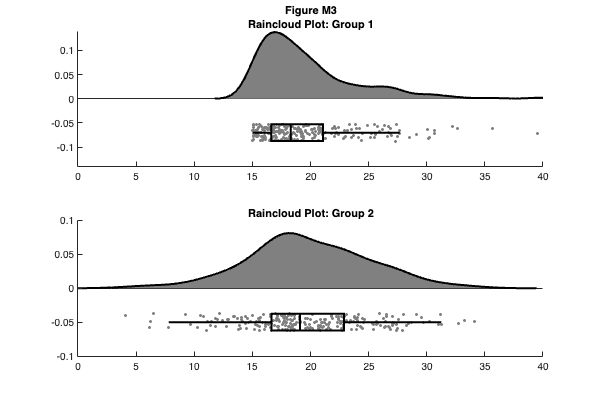

f3 = figure('Position', fig_position);
subplot(2, 1, 1)
h1 = raincloud_plot(d{1}, 'box_on', 1);
title(['Figure M3' newline 'Raincloud Plot: Group 1']);
set(gca, 'XLim', [0 40]);
box off
subplot(2, 1, 2)
h2 = raincloud_plot(d{2}, 'box_on', 1);
title('Raincloud Plot: Group 2');
set(gca, 'XLim', [0 40]);
box off

% save
print(f3, fullfile(figdir, '3Rain1.png'), '-dpng');

### This gives us the distribution (probability density plot), summary data (box plot), and raw observations all in one place. Now we’ll walk you through some of the options of the function, which you can use to change various aesthetic properties of the plot. The function only requires a vector of the data you want to plot as the input. Additionally, there are a variety of optional flags you can call to turn the boxplots on and off, to alter ('dodge') the position of the boxes and dots, and to change various aesthetics such as linewidth, colors, and so on. For example, by setting a few different flags we can create more colorful plots:

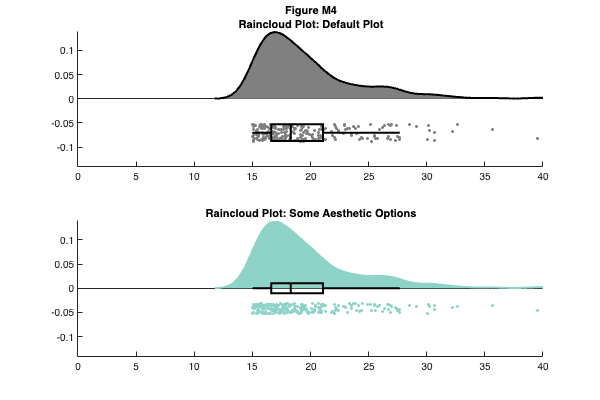

f4 = figure('Position', fig_position);
subplot(2, 1, 1)
h1 = raincloud_plot(d{1}, 'box_on', 1);
title(['Figure M4' newline 'Raincloud Plot: Default Plot']);
set(gca, 'XLim', [0 40]);
box off
subplot(2, 1, 2)
h2 = raincloud_plot(d{1}, 'box_on', 1, 'box_dodge', 1, 'box_dodge_amount',...
0, 'dot_dodge_amount', .3, 'color', cb(1,:), 'cloud_edge_col', cb(1,:));
title('Raincloud Plot: Some Aesthetic Options');
set(gca, 'XLim', [0 40]);
box off

% save
print(f4, fullfile(figdir, '4Rain2.png'), '-dpng');

### Here, we'll use the dot and box dodge options to create an overlapping set of raincloud plots, useful for group comparison. The function can be called repeatedly (e.g., from within a loop) - each iteration will overlay the previous. Note that here we're using the 'alpha' parameter to make the plot area see-through:

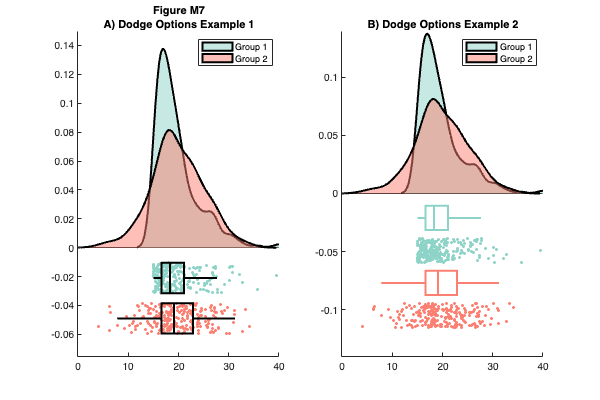

% example 1
f7 = figure('Position', fig_position);
subplot(1, 2, 1)
h1 = raincloud_plot(d{1}, 'box_on', 1, 'color', cb(1,:), 'alpha', 0.5,...
     'box_dodge', 1, 'box_dodge_amount', .15, 'dot_dodge_amount', .15,...
     'box_col_match', 0);
h2 = raincloud_plot(d{2}, 'box_on', 1, 'color', cb(4,:), 'alpha', 0.5,...
     'box_dodge', 1, 'box_dodge_amount', .35, 'dot_dodge_amount', .35, 'box_col_match', 0);
legend([h1{1} h2{1}], {'Group 1', 'Group 2'});
title(['Figure M7' newline 'A) Dodge Options Example 1']);
set(gca,'XLim', [0 40], 'YLim', [-.075 .15]);
box off

% example 2
subplot(1, 2, 2)
h1 = raincloud_plot(d{1}, 'box_on', 1, 'color', cb(1,:), 'alpha', 0.5,...
     'box_dodge', 1, 'box_dodge_amount', .15, 'dot_dodge_amount', .35,...
     'box_col_match', 1);
h2 = raincloud_plot(d{2}, 'box_on', 1, 'color', cb(4,:), 'alpha', 0.5,...
     'box_dodge', 1, 'box_dodge_amount', .55, 'dot_dodge_amount', .75,...
     'box_col_match', 1);
legend([h1{1} h2{1}], {'Group 1', 'Group 2'});
title('B) Dodge Options Example 2');
set(gca,'XLim', [0 40]);
box off

% save
print(f7, fullfile(figdir, '7Rain5.png'), '-dpng');

### Complex factorial situation with multiple groups {'idif', 'twilite'} and observations (sub-*)

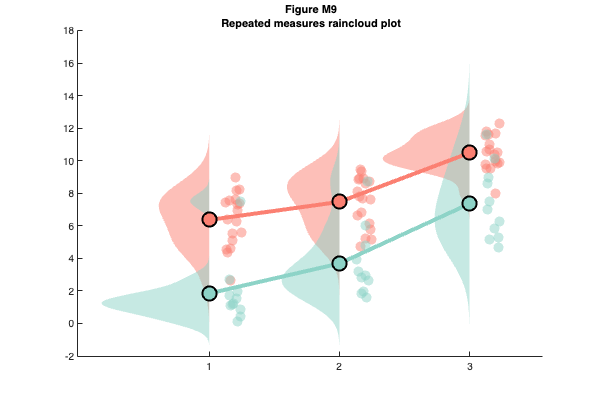


% grab 'repeated_measures_data.csv';
D = dlmread(fullfile(codedir, 'repeated_measures_data.csv'));

% read into cell array of the appropriate dimensions
for i = 1:3
    for j = 1:2
        data_all{i, j} = D(D(:, 2) == i & D(:, 3) ==j);
    end
end

% make figure
f9  = figure('Position', fig_position);
h   = rm_raincloud(data_all, cl);
set(gca, 'YLim', [-0.3 1.6]);
title(['Figure M9' newline 'Repeated measures raincloud plot']);

% save
print(f9, fullfile(figdir, '9RmRain1.png'), '-dpng');

### Using Lee2024, Idif2024:  Schaefer parcels are dots, distributions := ["idif", "twilite"], connect by medians, columns are subjects

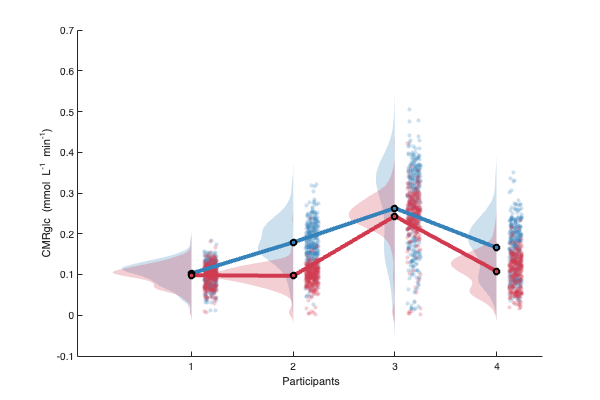

idif2024 = mlvg.Idif2024();
pwd0 = pushd(idif2024.derivatives_path);

[cb] = cbrewer2('Spectral', 12, 'pchip');
cl(1, :) = cb(11, :);  % blue is IDIF
cl(2, :) = cb(2, :);  % red is Twilite


%% CMRglc

nii_idif = idif2024.cmrglc(input_func="idif", stats="");
nii_twil = idif2024.cmrglc(input_func="twil", stats="");
% imagesc(nii_idif);
% imagesc(nii_twil);

data_all = cell(size(nii_idif, ndims(nii_idif)), 2);
data_idif = nii_idif.imagingFormat;
% data_idif.img = squeeze(data_idif.img(:,1,:));
data_twil = nii_twil.imagingFormat;
% data_twil.img = squeeze(data_twil.img(:,1,:));
for isub = 1:size(data_twil, 2)
    data_all{isub, 2} = double(data_twil.img(:, isub));
end
for isub = 1:size(data_idif, 2)
    if ~isempty(data_all{isub, 2})
        data_all{isub, 1} = double(data_idif.img(:, isub));
    end
end
% data_all = data_all(1:4, :);

% make figure
f_cmrglc  = figure('Position', fig_position);
h = rm_raincloud(data_all, cl);
%set(gca, 'YLim', [-0.3 1.6]);
xlabel("CMRglc (mmol L^{-1} min^{-1})");
ylabel("Participants");

% save
print(f_cmrglc, fullfile(figdir, 'cmrglc_raincloud.png'), '-dpng');

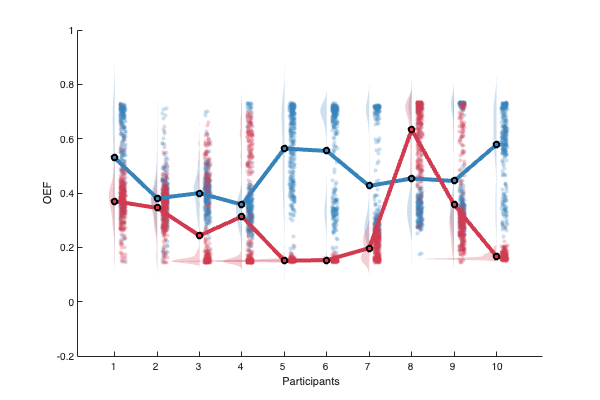


%% OEF

nii_idif = idif2024.mintunks(input_func="idif");
nii_twil = idif2024.mintunks(input_func="twil");
% imagesc(nii_idif);
% imagesc(nii_twil);

data_all = cell(size(nii_idif, ndims(nii_idif)), 2);
data_idif = nii_idif.imagingFormat;
data_idif.img = squeeze(data_idif.img(:,1,:));
data_twil = nii_twil.imagingFormat;
data_twil.img = squeeze(data_twil.img(:,1,:));
for isub = 1:size(data_twil, 2)
    data_all{isub, 2} = double(data_twil.img(:, isub));
end
for isub = 1:size(data_idif, 2)
    if ~isempty(data_all{isub, 2})
        data_all{isub, 1} = double(data_idif.img(:, isub));
    end
end
data_all = data_all(1:10, :);

% make figure
f_cmrglc  = figure('Position', fig_position);
h = rm_raincloud(data_all, cl);
%set(gca, 'YLim', [-0.3 1.6]);
xlabel("OEF");
ylabel("Participants");

% save
print(f_cmrglc, fullfile(figdir, 'oef_raincloud.png'), '-dpng');

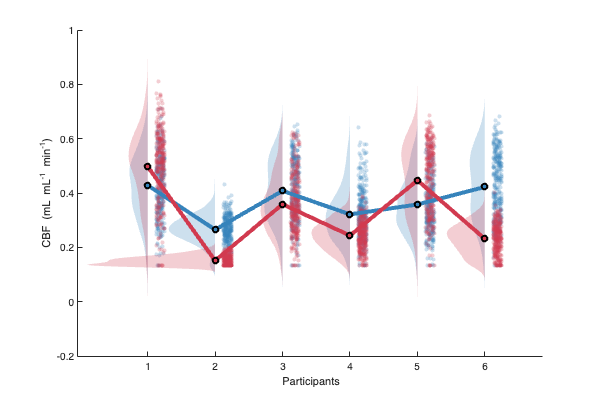


%% CBF

nii_idif = idif2024.raichleks(input_func="idif");
nii_twil = idif2024.raichleks(input_func="twil");
% imagesc(nii_idif);
% imagesc(nii_twil);

data_all = cell(size(nii_idif, ndims(nii_idif)), 2);
data_idif = nii_idif.imagingFormat;
data_idif.img = squeeze(data_idif.img(:,1,:));
data_twil = nii_twil.imagingFormat;
data_twil.img = squeeze(data_twil.img(:,1,:));
for isub = 1:size(data_twil, 2)
    data_all{isub, 2} = 60 * double(data_twil.img(:, isub));
end
for isub = 1:size(data_idif, 2)
    if ~isempty(data_all{isub, 2})
        data_all{isub, 1} = 60 * double(data_idif.img(:, isub));
    end
end
data_all = data_all(1:6, :);

% make figure
f_cbf  = figure('Position', fig_position);
h = rm_raincloud(data_all, cl);
%set(gca, 'YLim', [-0.3 1.6]);
xlabel("CBF (mL cm^{-3} min^{-1})");
ylabel("Participants");

% save
print(f_cbf, fullfile(figdir, 'cbf_raincloud.png'), '-dpng');

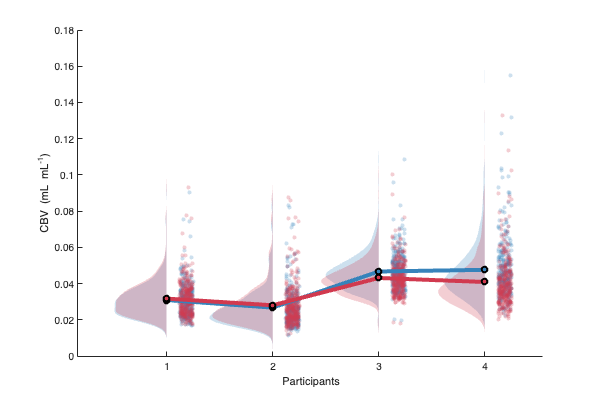


%% CBV

nii_idif = idif2024.martinv1(input_func="idif");
nii_twil = idif2024.martinv1(input_func="twil");
% imagesc(nii_idif);
% imagesc(nii_twil);

data_all = cell(size(nii_idif, 2), 2);
data_idif = nii_idif.imagingFormat;
data_twil = nii_twil.imagingFormat;
for isub = 1:size(data_idif, 2)
    data_all{isub, 1} = double(data_idif.img(:, isub));
end
for isub = 1:size(data_twil, 2)
    data_all{isub, 2} = double(data_twil.img(:, isub));
end

% make figure
f_cbv  = figure('Position', fig_position);
h = rm_raincloud(data_all, cl);
%set(gca, 'YLim', [-0.3 1.6]);
xlabel("CBV (mL cm^{-3})");
ylabel("Participants");

% save
print(f_cbv, fullfile(figdir, 'cbv_raincloud.png'), '-dpng');


popd(pwd0);


## Adjust FDG IDIFs by venous/arterial samples from 30-60 min of FDG

% 108293 fdg
% aif auc aif.json_metadata.timesMid >= 1800 -> 3.4058e6 decays/mL
% idif auc idif.json_metadata.timesMid >= 1800 -> 4.557413e6 decays/mL
% aif/idif ~ 0.7473

% 108237 fdg
% aif auc aif.json_metadata.timesMid >= 1800 -> 5.5512e6 decays/mL
% idif auc idif.json_metadata.timesMid >= 1800 -> 5.122963e6 decays/mL
% aif/idif ~ 1.0836

% 108250 fdg
% aif auc aif.json_metadata.timesMid >= 1800 -> 5.808673e6 decays/mL
% idif auc idif.json_metadata.timesMid >= 1800 -> 5.412725e6 decays/mL
% aif/idif ~ 1.0732

% 108306 fdg
% aif auc aif.json_metadata.timesMid >= 1800 -> 4.946465e6 decays/mL
% idif auc idif.json_metadata.timesMid >= 1800 -> 5.9134e6 decays/mL
% aif/idif ~ 0.8365

cd('/Volumes/PrecunealSSD/Singularity/CCIR_01211/derivatives/sub-108306/ses-20230227115809/pet')
aif = mlfourd.ImagingContext2("sub-108306_ses-20230227115809_trc-fdg_proc-TwiliteKit-do-make-input-func-nomodel_inputfunc-embed.nii.gz")
idif = mlfourd.ImagingContext2("sub-108306_ses-20230227115809_trc-fdg_proc-MipIdif_idif.nii.gz")
plot(aif)
plot(idif)
aifTimesMid = aif.json_metadata.timesMid;
idifTimesMid = idif.json_metadata.timesMid;
aifTimesMid(aifTimesMid > 1800)
atm = asrow(aifTimesMid(aifTimesMid > 1800))
trapz(atm, aif.imagingFormat.img(end-2:end))
[~,idx] = max(idifTimesMid >= 1803)
[~,idx] = max(idifTimesMid >= 3003)
trapz(idifTimesMid(376:436), idif.imagingFormat.img(376:436))
4.946465e6 / 5.9134e6
